## Definicion Datos

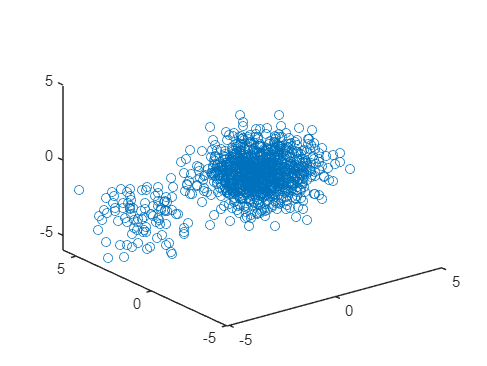

n = 3;
X1=randn(1000,n);
X2=[-3 3 -3]+randn(100,n);
X=[X1
 X2];
plot3(X(:,1),X(:,2),X(:,3),'o')

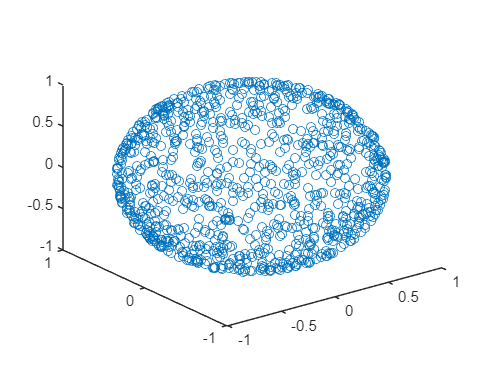


V=randn(1000,n);
for i = 1:length(V)
    V(i,:) = V(i,:)/norm(V(i,:));
end
plot3(V(:,1),V(:,2),V(:,3),'o')

V = V.';
Proy = X*V;

## Filtro Naive

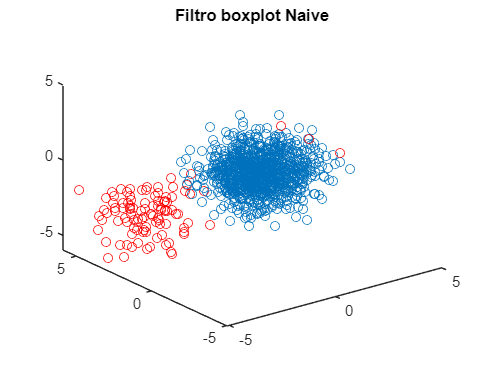

Asim = skewness(Proy);
aux = abs(Asim);
Maxasim = max(aux);
Indexmax = find(aux == Maxasim);
xproy = Proy(:,Indexmax);
ri=iqr(xproy);
Q3=prctile(xproy,75);
Q1 = prctile(xproy,25);
Li = Q1 - 1.5*ri;
Ls=Q3+1.5*ri;
I1 = find(xproy<Li);
I2=find(xproy>Ls);
I = [I1
    I2];
plot3(X(:,1),X(:,2),X(:,3),'o')
hold on
title('Filtro boxplot Naive')
plot3(X(I,1),X(I,2),X(I,3),'or')
hold off

## Filtro Boxplot Asimetria

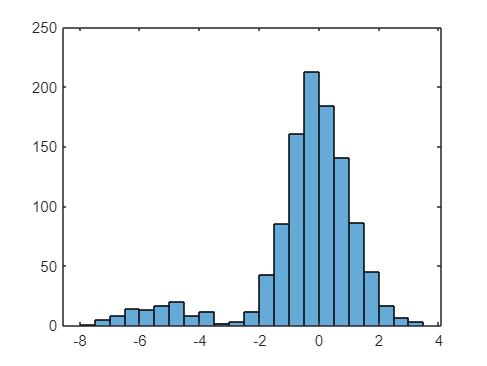

Asim = skewness(Proy);
aux = abs(Asim);
Maxasim = max(aux);
Indexmax = find(aux == Maxasim);
xproy = Proy(:,Indexmax);
histogram(xproy)

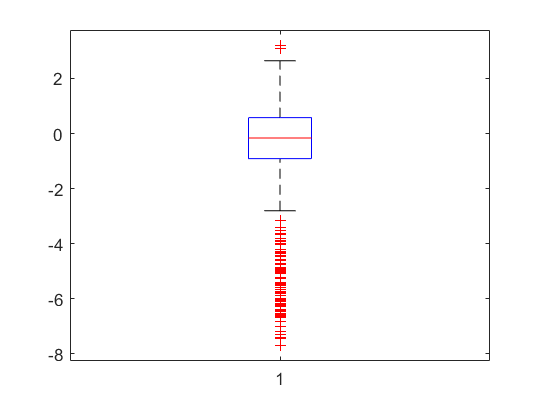

boxplot(xproy)

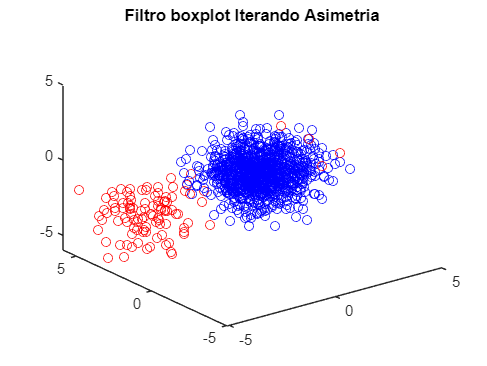

%%%%%%%%%%%
auxproy = xproy;
dataoutliers = NaN(1,1/10*length(xproy));

for i = 1:1/10*length(xproy)
    Q1 = prctile(auxproy,25);
    Q3 = prctile(auxproy,75);
    ri = iqr(auxproy);
    middle = median(auxproy);
    Limsup = Q3+1.5*ri;
    Liminf = Q1-1.5*ri;
    indoutliers = find(auxproy < Liminf | auxproy > Limsup);
    outliers = auxproy(indoutliers,:);
    if isempty(outliers)
        break
    end
    distances = abs(outliers - middle);
    [~, indexout] = max(distances);
    maxoutlier = outliers(indexout,:);
    indexoutliers = find(xproy == maxoutlier);
    auxproy(find(auxproy == maxoutlier),:) = [];
    dataoutliers(i) = indexoutliers;

end
auxproy;
dataoutliers(find(isnan(dataoutliers))) = [];
dataoutliers = dataoutliers.';

plot3(X(dataoutliers,1),X(dataoutliers,2),X(dataoutliers,3),'ro')
hold on
title('Filtro boxplot Iterando Asimetria')
datafiltradoa = X;
datafiltradoa(dataoutliers,:) = [];
plot3(datafiltradoa(:,1),datafiltradoa(:,2),datafiltradoa(:,3),'bo')
hold off

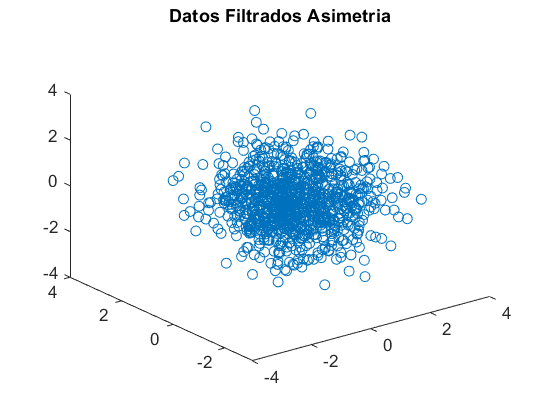

plot3(datafiltradoa(:,1),datafiltradoa(:,2),datafiltradoa(:,3),'o')
title('Datos Filtrados Asimetria')

## Filtro Boxplot con Kurtosis

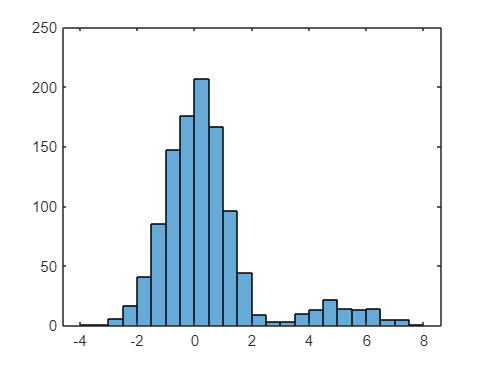


kurt = kurtosis(Proy);
aux = abs(kurt);
Maxkurt = max(aux);
Indexmax = find(aux == Maxkurt);
xproy = Proy(:,Indexmax);
histogram(xproy)

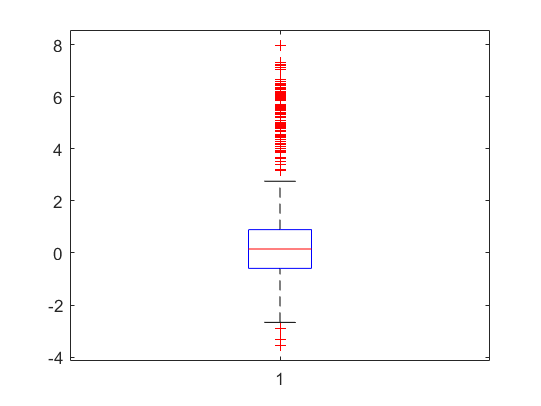

boxplot(xproy)

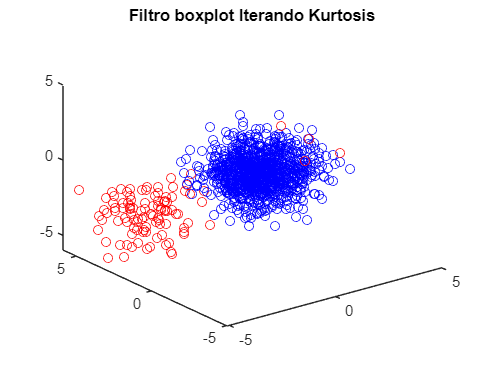

%%%%
auxproy = xproy;
dataoutliers = NaN(1,1/10*length(xproy));

for i = 1:1/10*length(xproy)
    Q1 = prctile(auxproy,25);
    Q3 = prctile(auxproy,75);
    ri = iqr(auxproy);
    middle = median(auxproy);
    Limsup = Q3+1.5*ri;
    Liminf = Q1-1.5*ri;
    indoutliers = find(auxproy < Liminf | auxproy > Limsup);
    outliers = auxproy(indoutliers,:);
    if isempty(outliers)
        break
    end
    distances = abs(outliers - middle);
    [~, indexout] = max(distances);
    maxoutlier = outliers(indexout,:);
    indexoutliers = find(xproy == maxoutlier);
    auxproy(find(auxproy == maxoutlier),:) = [];
    dataoutliers(i) = indexoutliers;

end

%auxproy;
dataoutliers(find(isnan(dataoutliers))) = [];
dataoutliers = dataoutliers.';
%plot3(X(:,1),X(:,2),X(:,3),'o')

plot3(X(dataoutliers,1),X(dataoutliers,2),X(dataoutliers,3),'ro')
hold on
title('Filtro boxplot Iterando Kurtosis')
datafiltradok = X;
datafiltradok(dataoutliers,:) = [];
plot3(datafiltradok(:,1),datafiltradok(:,2),datafiltradok(:,3),'bo')
hold off

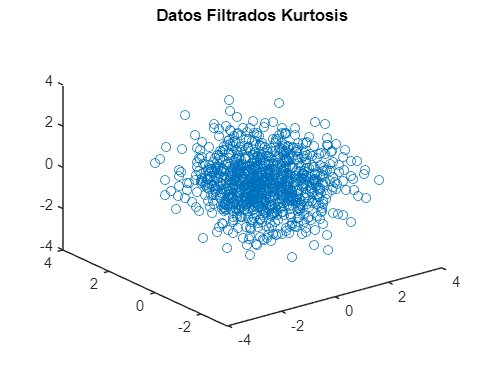

plot3(datafiltradok(:,1),datafiltradok(:,2),datafiltradok(:,3),'o')
title('Datos Filtrados Kurtosis')

## Variabilidad

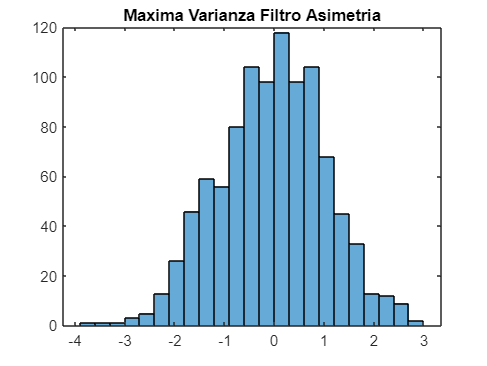

% Asimetria
proyeccionesa = datafiltradoa*V;
vara = var(proyeccionesa);
aux = abs(vara);
Maxvara = max(aux);
Indexmax = find(aux == Maxvara);
proyvara = proyeccionesa(:,Indexmax);
histogram(proyvara)
title('Maxima Varianza Filtro Asimetria')

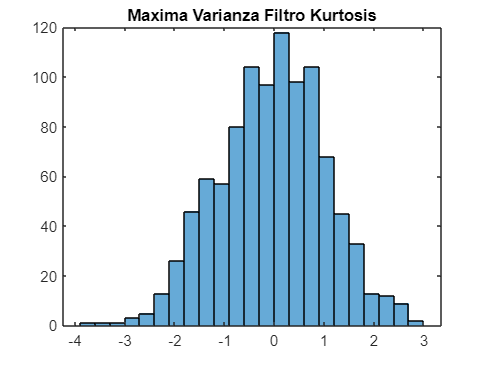

% Kurtosis
proyeccionesk = datafiltradok*V;
vark = var(proyeccionesk);
aux = abs(vark);
Maxvark = max(aux);
Indexmax = find(aux == Maxvark);
proyvark = proyeccionesk(:,Indexmax);
histogram(proyvark)
title('Maxima Varianza Filtro Kurtosis')

## Copula empirica

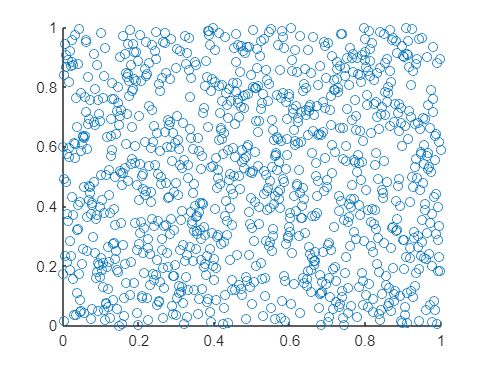

data1 = randn(1000,1);
data2 = exprnd(1,1000,1);

data = [data1 data2];
%sorted_d ata = sort(data);
n = length(data);

min1 = min(data(:,1));
max1 = max(data(:,1));
intervalo1 = (max1-min1)/n;
%x1 = min1:intervalo1:max1;
x1 = data(:,1);
y1 = zeros(n,1);

min2 = min(data(:,2));
max2 = max(data(:,2));
intervalo2 = (max2-min2)/n;
%x2 = min2:intervalo2:max2;
x2 = data(:,2);
y2 = zeros(n,1);

for i = 1:length(x1)
    y1(i) = sum(data1 <= x1(i)) / n;
end

for i = 1:length(x2)
    y2(i) = sum(data2 <= x2(i)) / n;
end


%real = cdf('Normal',x1,0,1);
%plot(x1, y1);

scatter(y1,y2)

%x = linspace(-10,10,1000);
%y = x.^3 + 4214810432421;
%plot(y1,y2, 'o')
%hold on
%xlabel('Data');
%ylabel('ECDF');
%plot(x1,real)
%hold off

## Con funcion

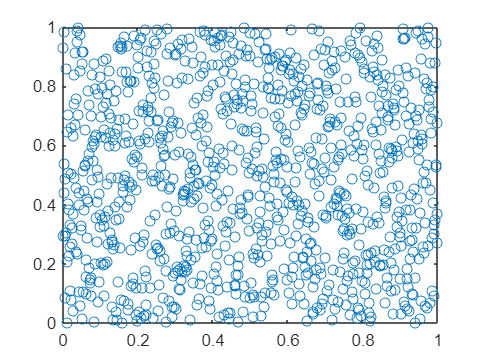

% Generacion de datos   
data1 = randn(1000,1);
data2 = exprnd(1,1000,1);
data = [data1 data2];
emp1 = empiric(data(:,1))';
emp2 = empiric(data(:,2))';
data = [emp1, emp2];
plot(data(:,1),data(:,2),'o')

%plot(data1,data2,'o')

## Datos dependientes

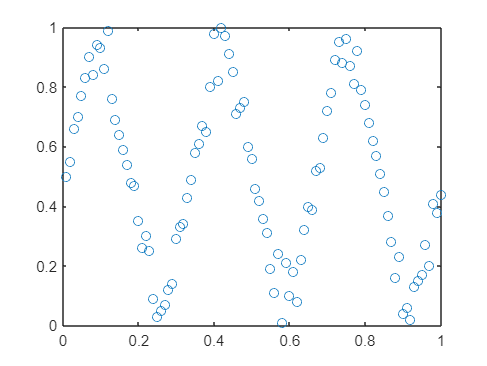

% Generacion de datos   
data11 = linspace(0,2*pi,100)';
data22 = sin(3*data11) + 0.1*randn(1,100)';
data2 = [data11 data22];
emp11 = empiric(data2(:,1))';
emp22 = empiric(data2(:,2))';
data2 = [emp11, emp22];
plot(data2(:,1),data2(:,2), 'o')

## Datos portafolio

data5 = readmatrix("5_Industry_Portfolios.csv")

data5 = 1.0e+05 *

       NaN       NaN       NaN       NaN       NaN       NaN
    1.9261    0.0001    0.0000    0.0000    0.0000    0.0000
    1.9261    0.0000    0.0000    0.0000    0.0000    0.0000
    1.9261    0.0000   -0.0000    0.0000    0.0000    0.0000
    1.9261   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    1.9261    0.0000    0.0000    0.0000    0.0001    0.0000
    1.9261    0.0000    0.0000    0.0000    0.0000    0.0000
    1.9270   -0.0000    0.0000    0.0000    0.0001    0.0000
    1.9270    0.0001    0.0000    0.0000    0.0000    0.0001
    1.9270    0.0000   -0.0000    0.0000    0.0000    0.0000


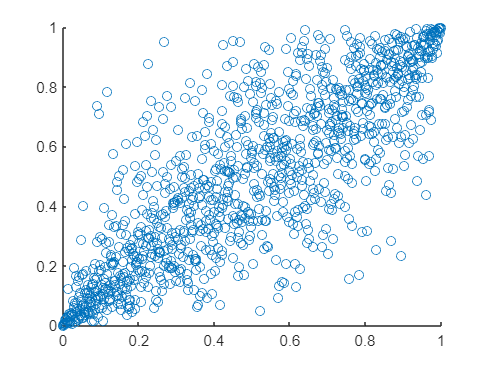

data5(1,:) = [];
data5(:,2);
data5(:,3);
emp1 = empiric(data5(:,2));
emp2 = empiric(data5(:,3));
scatter(emp1,emp2)

function [emp] = empiric(col)
    n = length(col);
    emp = [];
    for i = 1:length(col)
        ratio = (length(col(col<=col(i))))/n;
        emp = [emp, ratio];
    end

end
